# UWB Localization Using IEEE 802.15.4z

This example shows how to estimate the location of a single device as per the IEEE® 802.15.4z™ standard [ 2 ], using the Communications Toolbox™ Library for ZigBee® and UWB add-on.

## Overview

The IEEE 802.15.4z amendment [ 2 ] of the IEEE® 802.15.4 standard [ 1 ] is a MAC and PHY specification designed for ranging and localization using ultra wideband (UWB) communication. The very short pulse durations of UWB allow a finer granularity in the time domain and therefore more accurate estimates in the spatial domain. 

The key ranging and localization functionality of the 802.15.4z amendment includes 3 MAC-level techniques:

- Single-sided two-way ranging (SS-TWR) - One device estimates the distance between two devices by using frame transmission in both directions of a wireless 802.15.4z link. This technique is demonstrated in the [UWB Ranging using IEEE 802.15.4z](docid:comm_ug#example-UWBRanging) example.

- Double-sided two-way ranging (DS-TWR) - Both devices estimate the distance between the two devices by using frame transmission in both directions of a wireless 802.15.4z link.

- One-way ranging / time-difference of arrival (OWR/TDOA) - Network-assisted localization whereby one device communicates with a set of synchronized nodes to estimate the position of the device.

This example demonstrates the OWR/TDOA technique for uplink transmissions, by using MAC and PHY frames are compatible with the IEEE 802.15.4 standard [ 1 ] and the IEEE 802.15.4z amendment [ 2 ]. For more information on generating PHY-level IEEE 802.15.4z waveforms, see the [HRP UWB IEEE 802.15.4a/z Waveform Generation](docid:comm_ug#example-HRPUWBWaveformGenerationExample) example. For more information on generating IEEE 802.15.4 MAC frames, see the [IEEE 802.15.4 - MAC Frame Generation and Decoding](docid:comm_ug#example-lrwpanMACFramesExample) example.

## One-Way Ranging / Time-Difference of Arrival (OWR/TDOA)

One-way ranging (OWR) involves frame transmission either in the uplink or in the downlink direction. In the uplink case, the device to be localized periodically broadcasts short messages referred to as *blinks*. The IEEE 802.15.4z amendment [ 2 ] does not stipulate a specific frame format for the blinks, however it states that blinks should be as short as possible. These blink messages are received by a set of infrastructure nodes that are synchronized either through a wired backbone or via an UWB wireless communications link. In the downlink case, the synchronized nodes periodically transmit broadcast messages with a known time offset.

The time-difference of arrival (TDOA) between the periodic messages places the device in one hyperbolic surface for each pair of synchronized nodes [ 3 ]. The intersection of all hyperbolic surfaces (for every pair of synchronized nodes) gives the location estimate for the device.

This example demonstrates the uplink OWR case. 

## Setup

Confirm installation of the Communications Toolbox™ Library for ZigBee® and UWB add-on.

%commSupportPackageCheck('ZIGBEE');

#### Configure Network

Set up a network with 3 synchronized nodes and 1 device, in a 100x100 plane:

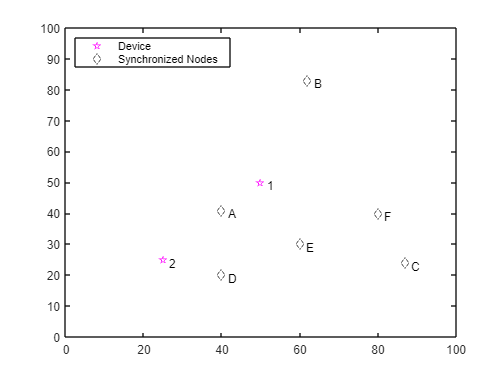

numDevices = 2;
numNodes = 6;

deviceLoc = [50 50;
             25 25]; 

nodeLoc = [40 41;
           62 83;
           87 24;
           40 20;
           60 30;
           80 40];
TDOA = nan(numNodes);
helperShowLocations(deviceLoc,nodeLoc);

Calculate the actual distance and time of flight (TOF) between nodes and the device.

actualDistances = pdist2(nodeLoc, deviceLoc)

actualDistances =           13.4536240470737          21.9317121994613
          35.1140997321589          68.7968022512675
          45.2216762183801            62.00806399171
          31.6227766016838          15.8113883008419
          22.3606797749979          35.3553390593274
          31.6227766016838          57.0087712549569


c = physconst('LightSpeed')% speed of light (m/s)

c =    299792458

actualTOF = actualDistances/c

actualTOF =       4.48764593239824e-08      7.31563173595958e-08
      1.17128029058552e-07      2.29481430954702e-07
      1.50843275111277e-07      2.06836637603839e-07
      1.05482228647939e-07      5.27411143239697e-08
      7.45871991716279e-08      1.17932716837484e-07
      1.05482228647939e-07      1.90160792020181e-07


sampleRate = 1e9;

samplesToDelay = actualTOF * sampleRate

samplesToDelay =           44.8764593239824          73.1563173595958
          117.128029058552          229.481430954702
          150.843275111277          206.836637603839
          105.482228647939          52.7411143239697
          74.5871991716279          117.932716837484
          105.482228647939          190.160792020181


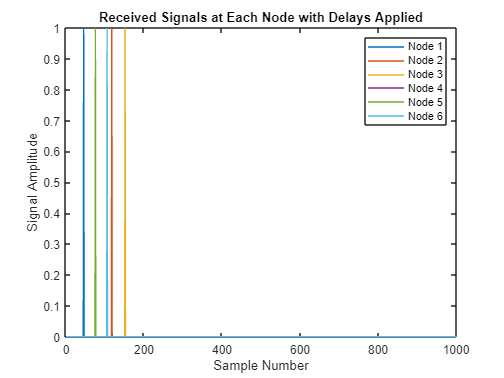

% Assuming a simple pulse signal
txSignal = [1; zeros(999, 1)];  % Short pulse followed by zeros

% Apply calculated delays to the signal for each node
for node = 1:numNodes
    delay = round(samplesToDelay(node));  % Round to nearest sample
    rxSignals(:, node) = [zeros(delay, 1); txSignal(1:end-delay)];  % Shift signal
end
% Plot to visualize
figure;
plot(rxSignals);
legend('Node 1', 'Node 2', 'Node 3', 'Node 4', 'Node 5', 'Node 6');
title('Received Signals at Each Node with Delays Applied');
xlabel('Sample Number');
ylabel('Signal Amplitude');

% OUR DATA
SNR = 30;  % in dB

The graph shows the delayed reception of signals at each node due to the differing distances from the transmitter. Each vertical line represents the reception of the signal by a different node, and the delay across the nodes is evident from the shift in the lines along the sample number axis. This plot is useful for observing how the time of flight (TOF) varies between the transmitter and each node.

#### Configure Blinks

Use a short (IEEE 802.15.4 MAC) data frame as a blink.

numBlinks = 1;

% MAC layer:
payload = '00'; 
cfg = lrwpan.MACFrameConfig( ...
        FrameType='Data', ...
        DestinationAddressing='Short address', ...
        SourceAddressing='Short address', ...
        SourcePANIdentifier='AB12', ...
        SourceAddress='CD77')

cfg =   MACFrameConfig with properties:

                       FrameType: 'Data'
   General MAC properties:
                  SequenceNumber: 0
           AcknowledgmentRequest: 0
           DestinationAddressing: 'Short address'
        DestinationPANIdentifier: '0000'
              DestinationAddress: '0001'
                SourceAddressing: 'Short address'
             SourcePANIdentifier: 'AB12'
                   SourceAddress: 'CD77'
    PANIdentificationCompression: 0
                    FramePending: 0
                    FrameVersion: '2011'
                        Security: 0
   Security properties:
    No properties.
   Beacon properties:
    No properties.
   "MAC Command" properties:
    No properties.

blinkMAC = lrwpan.MACFrameGenerator(cfg,payload);

% PHY layer:
% Ensure the Ranging field is enabled. 
% Also set the proper PSDU length.
blinkPHYConfig = lrwpanHRPConfig( ...
    Mode='HPRF', ...
    STSPacketConfiguration=1, ... % TO CHECK
    PSDULength=length(blinkMAC)/8, ...
    Ranging=true);
blinkPHY = lrwpanWaveformGenerator( ...
    blinkMAC, ...
    blinkPHYConfig);

% Cache preamble, to use in preamble detection. 
% Get the 1st instance out of the Nsync=PreambleDuration repetitions.
indices = lrwpanHRPFieldIndices(blinkPHYConfig); % length (start/end) of each field
blinkPreamble = blinkPHY( ...
    1:indices.SYNC(end)/blinkPHYConfig.PreambleDuration); % 1 of the Nsync repetitions

## Run Simulation

In the simulation loop, a blink propagates to each node with a propagation delay that is determined by their distinct distance. Next, each pair of nodes calculates the difference of their blink arrival times. As a result, the position of the device is estimated within a hyperbolic surface for each pair of nodes. The intersection of all surfaces gives the position estimate for the device. Here, a plot of 2D curves shows the intersection point to indicate the position estimate for the device.

Processing device 1...


Processing blink 1 for device 1...


xO =            49.999998602205

yO =           49.9999997406037

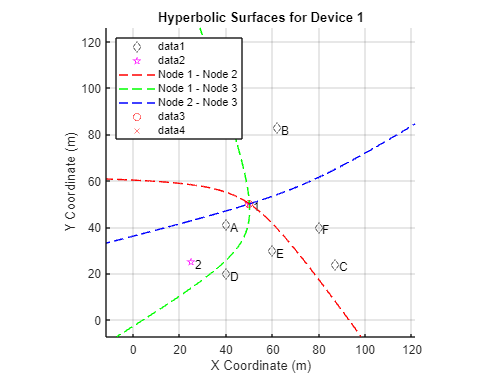

Processing device 2...


Processing blink 1 for device 2...


xO =           24.9999798082137
           39.240596340693


yO =           24.9999887356997
          32.5855610480199


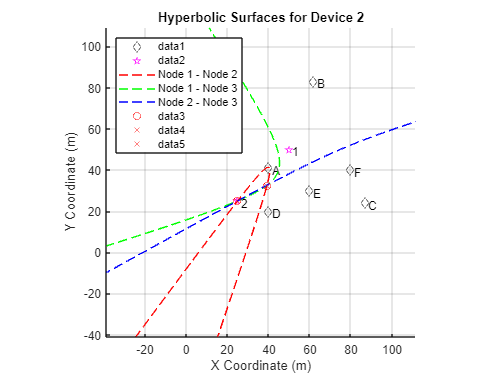

vfd = dsp.VariableFractionalDelay;
plotStr = {'r--', 'g--', 'b--'};  % Ajouter plus de couleurs si nécessaire

% Définissez les paires de nœuds que vous souhaitez analyser, par exemple, les nœuds (1,2), (1,3), et (2,3).
nodePairs = [1, 2; 
             1, 3; 
             2, 3];

numPairs = size(nodePairs, 1);

% Initialisation des cellules pour stocker les hyperboles
xCell = cell(numPairs, 1);
yCell = cell(numPairs, 1);



% Device loop
for devIdx = 1:numDevices
    fprintf('Processing device %d...\n', devIdx);


    % Initialisation des cellules pour stocker les hyperboles
    xCell = cell(numPairs, 1);
    yCell = cell(numPairs, 1);


    % Arrival time for each node
    arrivalTime = zeros(numNodes, 1);

    % Graph
    figure; hold on;
    leg = legend( ...
    'Device', ...
    'Synchronized nodes', ...
    'A-B', ...
    'A-C', ...
    'B-C', ...
    'Estimation', ...
    'Intersections', ...
    'location','northwest');
    
    plot(nodeLoc(:, 1), nodeLoc(:, 2), 'kd');
    for i = 1:size(nodeLoc, 1)
        text(nodeLoc(i, 1) + 1.5, nodeLoc(i, 2) - 1, char(64+i)); % Labels like A, B, C...
    end

    plot(deviceLoc(:,1), deviceLoc(:,2), 'mp');
    for j = 1:size(deviceLoc, 1)
        text(deviceLoc(j, 1) + 1.5, deviceLoc(j, 2) - 1, num2str(j)); % Labels like 1, 2, ...
    end

    % Blimk loop
    for idx = 1:numBlinks
        fprintf('Processing blink %d for device %d...\n', idx, devIdx);

        for nodeIdx = 1:numNodes
            % Calculs
            distance = norm(nodeLoc(nodeIdx, :) - deviceLoc(devIdx, :));
            tof = distance / 299792458;  % Vitesse de la lumière en m/s
            samplesToDelay = round(tof * blinkPHYConfig.SampleRate);

            reset(vfd);
            release(vfd);
            vfd.MaximumDelay = ceil(1.1 * samplesToDelay);

            delayedBlink = vfd( ...
            [blinkPHY; zeros(ceil(samplesToDelay), 1)], ...
            samplesToDelay); % noise 
            receivedBlink = awgn(delayedBlink, SNR); % noise
            % Estimation of the tof based on the preamble 
            arrivalTime(nodeIdx) = tof;
        end

        % Localization: Estimate position at the synchronized backbone for each pair of nodes.
        pairCnt = 0;
        for pairIdx = 1:size(nodePairs, 1)
            node1 = nodePairs(pairIdx, 1);
            node2 = nodePairs(pairIdx, 2);
           
            % Calculate Time Difference of Arrival (TDOA)
            distance = norm(nodeLoc(node1, :) - nodeLoc(node2, :));
            TDOA = arrivalTime(node1)-arrivalTime(node2);
           
            % Get hyperbolic surface for the TDOA between node1 and node2
            [x, y] = helperGetHyperbolicSurface(nodeLoc(node1, :), nodeLoc(node2, :), TDOA);

            % Accumulation des coordonnées
            xCell{pairIdx} = [xCell{pairIdx}, x];
            yCell{pairIdx} = [yCell{pairIdx}, y];

            plot(x, y, plotStr{pairIdx}, 'DisplayName', sprintf('Node %d - Node %d', node1, node2));
            legendInfo{end+1} = sprintf('Node %d - Node %d Hyperbola', node1, node2);
        end


        % Trouver les intersections après tous les binks traités pour ce dispositif
        [xC, yC] = helperFindHyperbolicIntersection(xCell, yCell);
        xO = mean(xC, 2)
        yO = mean(yC, 2)
        plot(xO, yO, 'ro')
        plot(xC', yC', 'rx')

        leg;
        title(sprintf('Hyperbolic Surfaces for Device %d', devIdx));
        xlabel('X Coordinate (m)');
        ylabel('Y Coordinate (m)');
        axis equal;
        axis([0 100 0 100]);  % Fixer les limites des axes entre 0 et 100
        grid on;
        hold off;
    end
end


%zoomInToEstimationArea(deviceLoc, xC, yC, xO, yO);

The IEEE 802.15.4z localization algorithm allows for multiple intersection points between 2 hyperbolic surfaces, thus either one or two possible localization answers exist. Calculate the localization error for each answer:

for idx = 1:numel(xO)
    fprintf('Coordinates being used for error calculation: Estimation (xO: %0.3f, yO: %0.3f), Device Location (x: %0.3f, y: %0.3f)\n', ...
            xO(idx), yO(idx), deviceLoc(1, 1), deviceLoc(1, 2));

    locError = sqrt(sum(([xO(idx), yO(idx)] - deviceLoc(1, :)).^2, 2));
    fprintf('Localization error for point #%d = %0.3f m.\n', idx, locError);
end

Coordinates being used for error calculation: Estimation (xO: 25.000, yO: 25.000), Device Location (x: 50.000, y: 50.000)


Localization error for point #1 = 35.355 m.


Coordinates being used for error calculation: Estimation (xO: 39.241, yO: 32.586), Device Location (x: 50.000, y: 50.000)


Localization error for point #2 = 20.470 m.


For localization methods that rely on estimating the time of arrival, errors in the distance estimate are primarily caused when the arrival time is not an integer multiple of the sample time. The largest distance error for such localization methods occurs when the arrival time lasts half a sample time more than an integer multiple of sample time. The smallest distance error occurs when the arrival time is an integer multiple of sample time. For the higher pulse repetition frequency (HRPF) mode of the high rate pulse repetition frequency (HRP) PHY used in this example, the symbol rate is 499.2 MHz and the number of samples per symbol is 10. The maximum distance estimation error is $0\ldotp 5\times c/\left(499\ldotp 2\times 10\right)$, which is approximately 3 cm.

In general, the larger channel bandwidth in UWB corresponds to shorter symbol duration and smaller ranging error as compared to narrowband communication. For the narrowband communication as specified in IEEE 802.11az, the channel bandwidth ranges from 20 MHz to 160 MHz. Considering the maximum distance error for narrowband communication, estimates for the localization error lie between 0 and 10 cm for 160 MHz and between 0 and 75 cm for 20 MHz. For more information regarding positioning with IEEE 802.11az, see the [802.11az Positioning Using Super-Resolution Time of Arrival Estimation](docid:wlan_ug#example-HERangingPositioningExample) example.

## Further Exploration

This example uses these objects and functions from the Communications Toolbox™ Library for ZigBee® and UWB add-on.

- lrwpan.MACFrameConfig: Create configuration for 802.15.4 MAC frames

- lrwpan.MACFrameGenerator: Generate 802.15.4 MAC frames

- lrwpanHRPConfig: HRP waveform configuration

- lrwpanWaveformGenerator: Create an IEEE 802.15.4a/z HRP UWB waveform

Some of these utilities are undocumented and their API or functionality may change in the future. To view the source code for any of these utilities, use the [edit](docid:matlab_ref#btk4bs6) function. For example, enter: 

`    edit lrwpan.MACFrameConfig` 

at the MATLAB® command line to open `lrwpan.MACFrameConfig`.

## Selected Bibliography

1 - "IEEE Standard for Low-Rate Wireless Networks," in IEEE Std 802.15.4-2020 (Revision of IEEE Std 802.15.4-2015), pp.1-800, 23 July 2020, doi: 10.1109/IEEESTD.2020.9144691.

2 - "IEEE Standard for Low-Rate Wireless Networks – Amendment 1: Enhanced Ultra Wideband (UWB) Physical Layers (PHYs) and Associated Ranging Techniques," in IEEE Std 802.15.4z-2020 (Amendment to IEEE Std 802.15.4-2020), pp.1-174, 25 Aug. 2020, doi: 10.1109/IEEESTD.2020.9179124.

3 - Wong, S.; Zargani, R. Jassemi; Brookes, D. & Kim, B. "Passive target localization using a geometric approach to the time-difference-of-arrival method", Defence Research and Development Canada Scientific Report, DRDC-RDDC-2017-R079, June 2017, pp. 1-77.

*Copyright 2021 The MathWorks, Inc.*